# Example 6.27: NNs as Basis Function Models

Note: this script reproduces Example 6.27 (Section 6.7.1) of **Statistics for Chemical Engineers**: a small neural network seen as a model built from basis functions. Victor Z UW-Madison, 2020 basis functions for neural nets [https://www.mathworks.com/help/stats/rsmdemo.html](https://www.mathworks.com/help/stats/rsmdemo.html)

clc; clear all; close all hidden; format long e;

## Model and fit

we try to fit this nonlinear model

x=linspace(-1,1,20);
y= sin(4*x)+sin(8*x)+exp(-x);

data.x=x;
data.y=y;
data.m=6; % number of basis functions (perceptrons)
data.n=length(x);

% parameters are mix weights, evidence, and bias
beta=ones(3*data.m,1);

options = optimoptions(@lsqnonlin,'Algorithm','trust-region-reflective','Display','iter','MaxFunctionEvaluations',5000);
[betahat,resnorm,residual,exitflag,output,lambda,jacobian] = lsqnonlin(@myfun,beta,[],[],options,data);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0         19           233.175                               47
     1         38           21.0087          2.7573              4.3      
     2         57           17.2181         9.06069             2.99      
     3         76            16.151         4.77653            0.396      
     4         95            16.151         11.8961            0.396      
     5        114           16.0354             2.5             1.21      
     6        133           16.0354             2.5             1.21      
     7        152           15.7731           0.625            0.236      
     8        171           15.7315            1.25            0.523      
     9        190            15.378          0.3125            0.148      
    10        209           15.2589           0.625            0.154      
    11        228           15.2589      


display(betahat)

betahat =     -4.506816231228653e+00
    -1.164136126339338e+01
     1.535731211607385e+00
    -4.829753988373636e+00
    -7.079767198303984e+00
     1.482825972927597e+00
    -1.440025851048366e+01
     1.763898048621598e+00
     4.930156273749568e+01
     1.296698435568633e+01
     8.911375337008520e-01
    -4.871281591825800e+01
    -5.761087846775911e+00
    -6.297473589927462e+00
    -6.969844285198794e-01


yhat=myfun(betahat,data)+data.y';

xv=linspace(-1,1)';
figure(1)
subplot(2,2,1)
plot(xv,myfun2(betahat,xv,data.m),'black','LineWidth',1.5)

n =    100

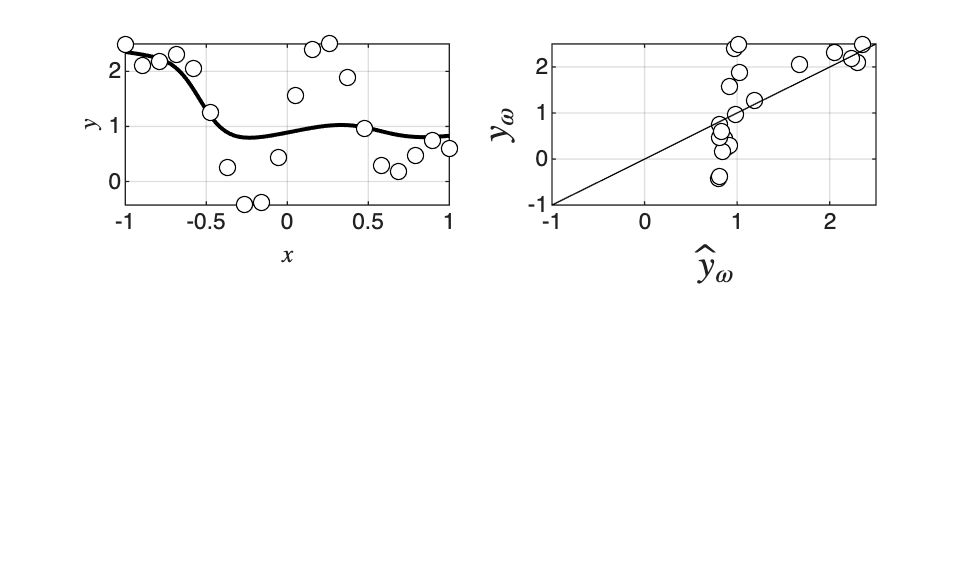

hold on
plot(x,y,'blacko','MarkerFaceColor','w')
grid on
 ylabel('$y$','Interpreter','latex')
  xlabel('$x$','Interpreter','latex')
subplot(2,2,2)
xx=linspace(-1,2.5);
plot(yhat,data.y','blacko','MarkerFaceColor','w')
hold on
plot(xx,xx,'black')
axis([-1,2.5,-1,2.5])
 ylabel('$y_\omega$','Interpreter','latex','FontSize',14)
  xlabel('$\hat{y}_\omega$','Interpreter','latex','FontSize',14)
grid on
print -depsc ch6_basis_nn_fit.eps

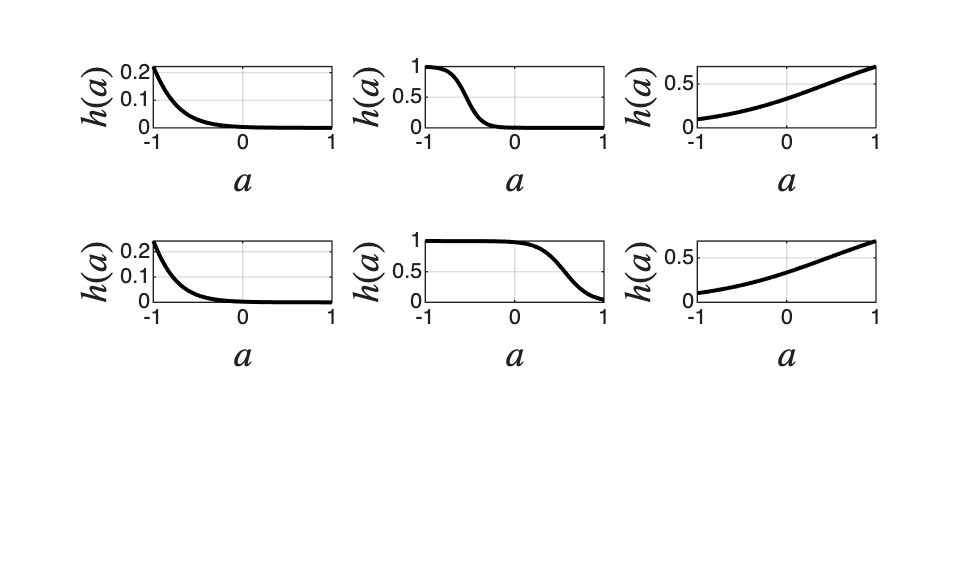


figure(2)
b=betahat;
for k=1:data.m
    theta(k)=b(k);
        w(k)=b(1*data.m+k);
     bias(k)=b(2*data.m+k);
end

for k=1:data.m
  z = theta(k)*xv'+bias(k);
  yn = 1./(1+exp(-z));  
  subplot(3,3,k)
  plot(xv,yn,'black','LineWidth',1.5)
  grid on
  ylabel('$h(a)$','Interpreter','latex','FontSize',14)
  xlabel('$a$','Interpreter','latex','FontSize',14)
end
print -depsc ch6_basis_nn.eps

## Hessian eigenvalues

hessian is approximated as

H=full(jacobian'*jacobian);

% check eigenvalues

lambda=eig(H)

lambda =     -4.066623671365293e-16
     7.287673562390680e-17
     1.220780795100126e-13
     4.289960480389229e-09
     7.772759919646832e-08
     5.283648517636834e-07
     1.082883262914596e-05
     7.427246780968386e-05
     1.991293536643894e-04
     2.063746823223649e-03
     7.851820272731154e-03
     4.182918360158319e-02
     9.149147227295991e-02
     1.394209015995783e-01
     7.533869274565330e-01


## functions

function F=myfun(b,data)

for k=1:data.m
    theta(k)=b(k);
        w(k)=b(1*data.m+k);
     bias(k)=b(2*data.m+k);
end

y=zeros(data.n,1);

for k=1:data.m
    z = theta(k)*data.x'+bias(k);
  yn = 1./(1+exp(-z));  
   y = y + w(k)*yn;
end

F=y-data.y';

end

function F=myfun2(b,x,m)

n=length(x)

for k=1:m
    theta(k)=b(k);
        w(k)=b(1*m+k);
     bias(k)=b(2*m+k);
end

y=zeros(n,1);

for k=1:m
    z = theta(k)*x+bias(k);
  yn = 1./(1+exp(-z));  
   y = y + w(k)*yn;
end

F=y;

end

## Note

As in the book, the Hessian has eigenvalues near zero: the parameters are not unique and uncertain, so NNs are flexible but prone to overparameterization and overfitting.